% Parameterize the arm
rho = 0.0254; % M, Radius
 
%% Construct pose matrices
% Transformations from world frame to each muscle

% Orientation of muscles in world frame:
orntn_muscles = eul2rotm([0, -pi/6, 0], 'xyz');

% Posese of muscle in world frame
% Muscles are arranged in equilateral triangle with radius rho
g_o = SE3(eul2rotm([0, -pi/2, 0], 'xyz'), [0 0 0]);
g_A = SE3(eul2rotm([0, 0, 4*pi/3], 'xyz') * orntn_muscles, [sqrt(3)/2, -1/2, 0] * rho);
g_B = SE3(eul2rotm([0, 0, 2*pi/3], 'xyz') * orntn_muscles, [-sqrt(3)/2, -1/2, 0] * rho);
g_C = SE3(orntn_muscles, [0, 1, 0] * rho);

% Calculate transformatiosn from base-curve location to muscle bases
g_o_A = inv(g_o) * g_A;
g_o_B = inv(g_o) * g_B;
g_o_C = inv(g_o) * g_C;

%% Calculate adjoint matrices
% Adjoints for each muscle, centered on the base curve
ad_o_A = ad_se3(g_o_A);
ad_o_B = ad_se3(g_o_B);
ad_o_C = ad_se3(g_o_C);

% The inverse: Adjoints centerd on each muscle, mapping from the base
% curve.
ad_A_o = inv(ad_o_A);
ad_B_o = inv(ad_o_B);
ad_C_o = inv(ad_o_C);

l_0 = 0.1; % Default length

% TODO: Maybe this could just be one function? Muscle2D.create_muscles()?
% Construct muscle objects
kappa_0 = [0 0 0]';
muscle_o = Muscle3D(l_0, kappa_0, 'adjoint_X_o', eye(4), 'g_0', g_o);
muscle_A = Muscle3D(l_0, kappa_0, "adjoint_X_o", ad_A_o, "g_0", g_o * g_o_A);
muscle_B = Muscle3D(l_0, kappa_0, "adjoint_X_o", ad_B_o, "g_0", g_o * g_o_B);
muscle_C = Muscle3D(l_0, kappa_0, "adjoint_X_o", ad_C_o, "g_0", g_o * g_o_C);

muscles = [muscle_A, muscle_B, muscle_C];

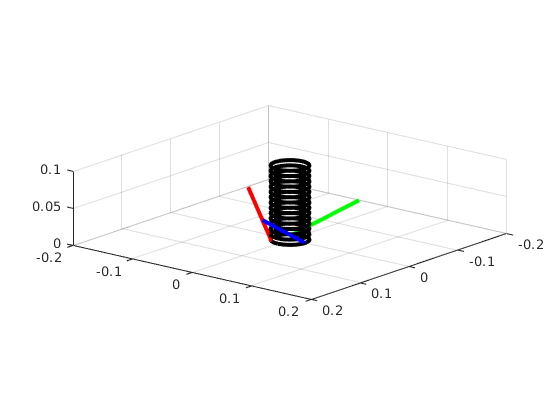

% Initialzie Plotting
muscle_A.color = [1 0 0];
muscle_B.color = [0 1 0];
muscle_C.color = [0 0 1];

% Test plotting
% TODO: Wrap this into its own function?
fig = figure();
ax = axes(fig);

% TODO: Add the color as a property of the muscle object.
line_options = struct('LineWidth', 3);

for i = 1 : length(muscles)
    muscles(i).plot_muscle(ax, 'line_options', line_options);
end

h_o_tilde_0 = [muscle_A.l; 0; 0; 0; 0; 0];

n_circles = 15;
t_circles = linspace(0, 1, n_circles);
v_lh_circles = matlab.graphics.primitive.Line.empty(0, n_circles);
for i = 1 : n_circles
    v_lh_circles(i) = line(0, 0, 0, 'color', 'k', line_options);
    plot_circle(v_lh_circles(i), rho, g_o * expm_se3(h_o_tilde_0 * t_circles(i)) * inv(g_o));
end

axis equal
border_length_cm = 20;
xlim(ax, [-1, 1] * border_length_cm/100);
ylim(ax, [-1, 1] * border_length_cm/100);

view([129.400 16.000])
grid on

% Calculate N matrix
mat_M = zeros(6);
mat_V = zeros(6, length(muscles));

for i = 1 : length(muscles)
    muscle_i = muscles(i);
    v_i = muscle_i.adjoint_X_o' * [1; 0; 0; 0; 0; 0];
    mat_V(:, i) = muscle_i.adjoint_X_o' * [1; 0; 0; 0; 0; 0];
    mat_M = mat_M + muscle_i.adjoint_X_o' * blkdiag(eye(3), zeros(3)) * muscle_i.adjoint_X_o;
end

mat_N = pinv(mat_M) * mat_V;

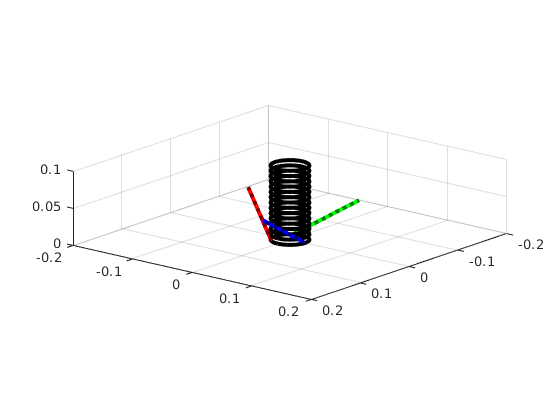

% Construct unstrained muscles
if exist('muscles_unstrained', 'var')
    delete(muscles_unstrained)
end

muscles_unstrained = copy(muscles);
for i = 1 : length(muscles) 
    % "Unstrained" line handles: Copy of actual line handles, but darker
    % Displays muscles if they had the same curvature but the actual
    % intended and unstrained length
    hsv_gains = diag([1, 1, 0.5]);
    muscles_unstrained(i).lh.Color = hsv2rgb(rgb2hsv(muscles(i).lh.Color) * hsv_gains);
    %v_lh_unconstrained(i).Color = 'k';
    muscles_unstrained(i).lh.LineStyle = ':';
end

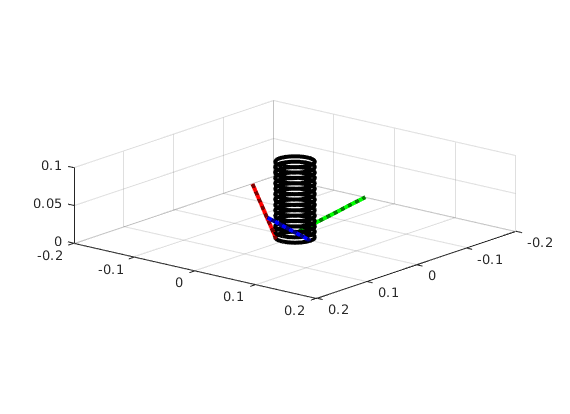

set(fig, 'visible', true)

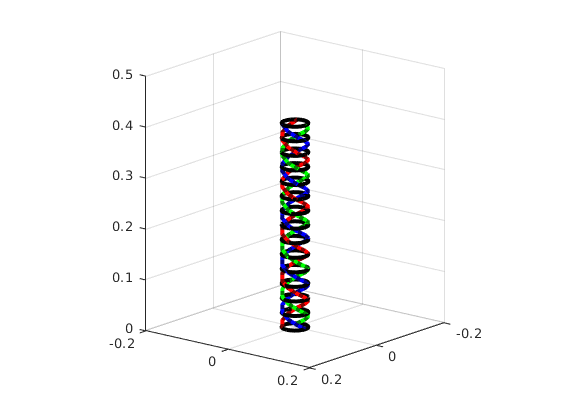

l_A = 0.8; % Red
l_B = 0.8; % Green
l_C = 0.8;  % Blue
v_l = [l_A; l_B; l_C];

% Calculate base curve curvature
h_o_tilde = mat_N * v_l;

muscle_o.h_tilde = h_o_tilde;

% Plot transform frames
if exist('gh_tf_o', 'var')
    delete(gh_tf_o)
end
if false
    gh_tf_o = muscle_o.plot_tforms(ax, 'plot_options', struct('FrameSize', rho));
end

% Calculate and plot individual muscle lengths
for i = 1 : length(muscles)
    muscles(i).h_tilde = muscles(i).adjoint_X_o * h_o_tilde;
    
    muscles_unstrained(i).h_tilde = muscles(i).h_tilde;
    muscles_unstrained(i).l = v_l(i);
    
    muscles(i).plot_muscle(ax, muscles(i).lh, 'resolution', 40);
    muscles_unstrained(i).plot_muscle(ax, muscles_unstrained(i).lh, 'resolution', 40);
end
for i = 1 : length(v_lh_circles)
    plot_circle(v_lh_circles(i), rho, g_o*expm_se3(h_o_tilde * t_circles(i))*inv(g_o));
end

function circle_points_world = plot_circle(lh, r, g_o, options)
    arguments
        lh
        r = 1;
        g_o = eye(4);
        options.t = linspace(0, 2*pi, 20)
    end
    
    circle_points_body = [cos(options.t); sin(options.t); zeros(size(options.t))] * r;
    circle_points_world = g_o(1:3, 1:3) * circle_points_body + g_o(1:3, 4);
    lh.XData = circle_points_world(1, :);
    lh.YData = circle_points_world(2, :);
    lh.ZData = circle_points_world(3, :);
end